# Example 4.2: Estimation for Weibull RV using Moment-Matching

Note: this script reproduces Example 4.2 (Section 4.1.1) of **Statistics for Chemical Engineers**: estimating the Weibull parameters (true values beta = 1, xi = 2) by matching moments. Victor Z UW-Madison, 2023 Weibull moment example

clc; clear all; close all hidden;

## Few data

try few data points

S=10;

% generate data using true model
beta=1 %(scale)

beta =      1

xi=2 %(shape)

xi =      2

rng(1);
X=wblrnd(beta,xi,S,1);

% estimates of moments
Ehat=mean(X)

Ehat =    1.2618e+00

Vhat=var(X)

Vhat =    4.6006e-01


% solve moment matching equations numerically
p0=[1,1];
opt = optimoptions('fsolve','Display','iter');
p = fsolve(@myfun,p0,opt,X);


                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3            0.360083                            1.43              1
     1          6            0.118108       0.720841            0.428              1
     2          9          0.00662554       0.261688           0.0694              1
     3         12         8.27513e-05       0.133282          0.00701              1
     4         15         1.95482e-08      0.0184452         0.000106              1
     5         18         1.17592e-15    0.000293999         2.59e-08              1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the 


% estimated parameters
betahat=p(1)

betahat =    1.4228e+00

xihat=p(2)

xihat =    1.9389e+00

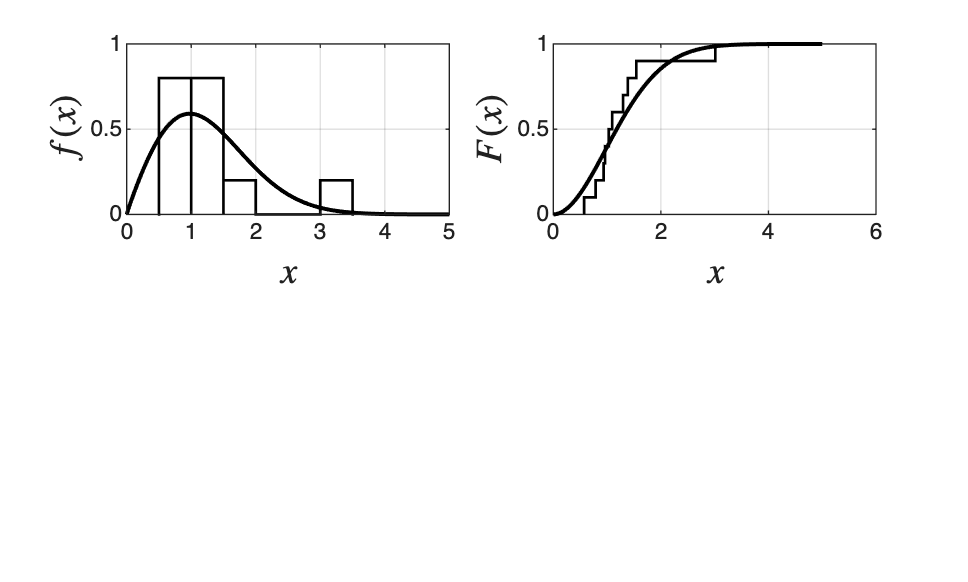


% compare truth against estima
subplot(2,2,1)
histogram(X,'BinWidth',0.5,'Normalization','pdf','EdgeColor','black','FaceColor','none','LineWidth',1)
hold on
x=linspace(0,5,100);
plot(x,wblpdf(x,betahat,xihat),'color','black','LineWidth',1.5)
xlabel('$x$','Interpreter','latex','FontSize',14)
ylabel('$f(x)$','Interpreter','latex','FontSize',14)
grid on
axis([0 5 0 1])

% compute and plot empirical cdf 
subplot(2,2,2)
[F,t]=ecdf(X);
stairs(t,F,'LineWidth',1,'Color','black')
hold on
plot(x,wblcdf(x,betahat,xihat),'color','black','LineWidth',1.5)
xlabel('$x$','Interpreter','latex','FontSize',14)
ylabel('$F(x)$','Interpreter','latex','FontSize',14)
title('')
grid on

## More data

try more data points

S=100;
rng(1);

% generate data using true model
beta=1 %(scale)

beta =      1

xi=2 %(shape)

xi =      2

X=wblrnd(beta,xi,S,1);

% estimates of moments
Ehat=mean(X)

Ehat =    9.2538e-01

Vhat=var(X)

Vhat =    2.6699e-01


% solve moment matching equations numerically
p0=[1,1];
opt = optimoptions('fsolve','Display','iter');
p = fsolve(@myfun,p0,opt,X)


                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          3            0.542876                            2.12              1
     1          6           0.0954641       0.295935            0.375              1
     2          9           0.0101326       0.303013           0.0847              1
     3         12         0.000353523       0.203829           0.0131              1
     4         15         9.04367e-07      0.0571117         0.000631              1
     5         18         7.34309e-12     0.00321309         1.79e-06              1
     6         21         4.87549e-22      9.216e-06         1.46e-11              1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the 

p =    1.0420e+00   1.8589e+00



% estimated parameters
betahat=p(1)

betahat =    1.0420e+00

xihat=p(2)

xihat =    1.8589e+00

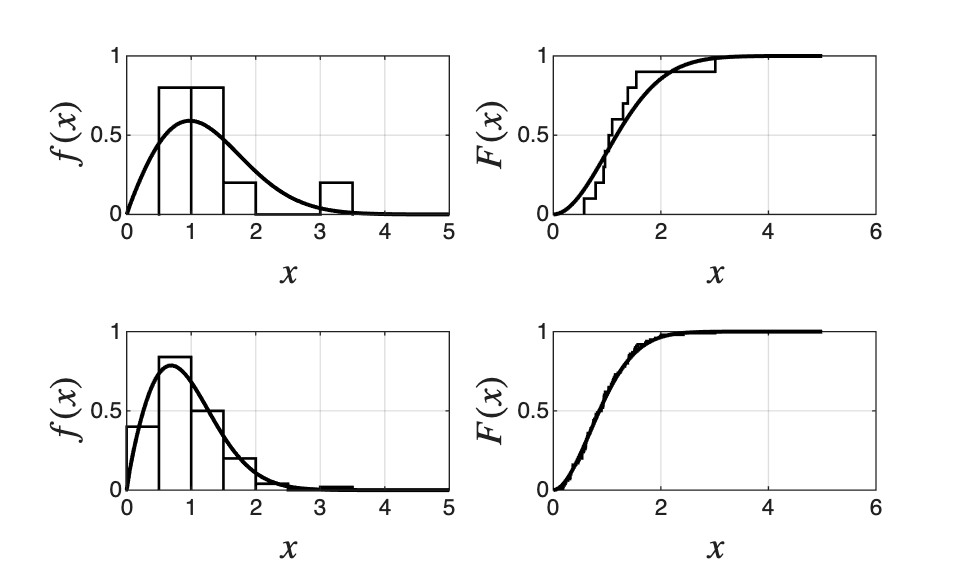


% compare truth against estima
subplot(2,2,3)
histogram(X,'BinWidth',0.5,'Normalization','pdf','EdgeColor','black','FaceColor','none','LineWidth',1)
hold on
x=linspace(0,5,100);
plot(x,wblpdf(x,betahat,xihat),'color','black','LineWidth',1.5)
xlabel('$x$','Interpreter','latex','FontSize',14)
ylabel('$f(x)$','Interpreter','latex','FontSize',14)
grid on
axis([0 5 0 1])

% compute and plot empirical cdf 
subplot(2,2,4)
[F,t]=ecdf(X);
stairs(t,F,'LineWidth',1,'Color','black')
hold on
plot(x,wblcdf(x,betahat,xihat),'color','black','LineWidth',1.5)
xlabel('$x$','Interpreter','latex','FontSize',14)
ylabel('$F(x)$','Interpreter','latex','FontSize',14)
title('')
grid on

print -depsc ch4_weibull_moments_example.eps



function err=myfun(param,X)
% compute empirical estimates
Ehat=mean(X);
Vhat=var(X);

% get theoretical mean and std
beta=param(1);
xi=param(2);
[E,V]=wblstat(beta,xi);

% mismatch error
err(1)=E-Ehat;
err(2)=V-Vhat;
err=err';
end

## Note

As in the book, the estimates vary significantly with few data but improve as S increases: having sufficient data matters.